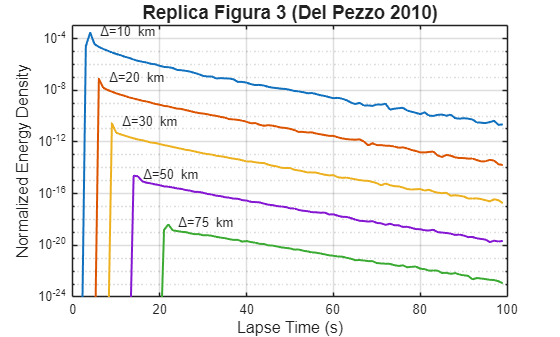

%% VISUALIZZAZIONE "WATERFALL" CORRETTA
% Assicurati di avere il file 'prova_bug_scat.dat' generato dalla simulazione che ha prodotto le curve rosse.

filename_hist = 'histo_toro.dat'; 
dists_vec = [10, 20, 30, 50, 75];     

% Caricamento Dati
try
    EnergyMatrix = dlmread(filename_hist); 
    % Se necessario, trasponiamo per avere (Tempo x Distanze)
    if size(EnergyMatrix, 2) ~= length(dists_vec)
        EnergyMatrix = EnergyMatrix';
    end
catch
    error('File dati non trovato.');
end

t_axis = 0:(size(EnergyMatrix, 1)-1);

figure('Name', 'Replica Figura 3 - Waterfall', 'Color', 'w');
hold on;

% Fattori di scala (dal caption Fig. 3)
scaling = [1, 1e-3, 1e-6, 1e-9, 1e-12];

% Colori (nero per tutte, o colorate se preferisci)
plot_colors = lines(5); 

% ... (codice precedente di setup figura e assi) ...

for i = 1:length(dists_vec)
    % 1. Prendiamo la curva originale
    curve_original = EnergyMatrix(:, i);
    
    % 2. Applichiamo lo scaling (cascata)
    curve_shifted = curve_original * scaling(i);
    
    % --- TRUCCO PER FIGURA 3 ---
    % Sostituiamo gli zeri con un valore piccolissimo (sotto il limite dell'asse Y)
    % In questo modo semilogy disegnerà una linea che sale dal basso.
    curve_shifted(curve_shifted == 0) = 1e-30; 
    
    % 3. Plot
    semilogy(t_axis, curve_shifted, 'Color', plot_colors(i,:), 'LineWidth', 1.5);
    
    % Etichette (come prima)
    [max_val, idx_max] = max(curve_shifted);
    if max_val > 1e-25 % Scriviamo solo se c'è un picco visibile
        text(t_axis(idx_max)+2, max_val, sprintf('\\Delta=%d km', dists_vec(i)), 'FontSize', 10);
    end
end

% ... (impostazioni assi e limiti rimangono uguali) ...

% --- IMPOSTAZIONI ASSI (COPIA DEL PAPER) ---
set(gca, 'YScale', 'log');
grid on;
box on;

xlabel('Lapse Time (s)', 'FontSize', 12);
ylabel('Normalized Energy Density', 'FontSize', 12);
% title('Replica Figura 3 (Del Pezzo 2010)', 'FontSize', 14);

% LIMITI ASSI (Fondamentali!)
xlim([0, 100]);        % Tempo 0-100s
ylim([1e-24, 1e-3]);   % Da 10^-24 a 10^-3 (Copre tutte le curve shiftate)

% Ticks manuali per asse Y (opzionale, per bellezza)
yticks([1e-24, 1e-20, 1e-16, 1e-12, 1e-8, 1e-4]);

hold off;